clear
format shortG
warning off;
SetRNG(111);
% generate input data
%hierarchy 1 and 2 generation
k = 4;
dim = 100;
mu_range = [-1000 1000];
sigma = 100;
split_num = 2;
[center1,mu_mat] = subcluster_centroid(k,dim,split_num,mu_range,sigma); 
means = [];


%hierarchy 3 generation
center2 = [];  
for i = 1:size(center1,1)
    r = normrnd(0,20,[3,100])+center1(i,:);
    center2 = [center2;r];
end
center = center2;

% data generation with the given centroids
dim = 100;
num = 100;
sigma = 5;
[inputs,c] = subcluster_simulate(center,dim,num,sigma);
assign_id1 = repelem([1:4],600)';
assign_id2 = repelem([1:8],300)';
assign_id3 = repelem([1:24],100)';

% inputs = [inputs,assign_id1,assign_id2,assign_id3];
% %inputs = inputs(randperm(size(inputs, 1)),:);
% assign_id1 = inputs(:,end-2);
% assign_id2 = inputs(:,end-1);
% assign_id3 = inputs(:,end);
% inputs = inputs(:,1:end-3);
data = inputs';

c2c_dist_layer1 = norm(mu_mat(2,:)'-mu_mat(1,:)',2);
c2c_dist_layer2 = norm(center1(2,:)'-center1(1,:)',2);
c2c_dist_layer3 = norm(center2(2,:)'-center2(1,:)',2);

layers = ["centroid A and centroid B";"centroid A1 and centroid A2";"centroid A1α and centroid A1β"];
distance = [c2c_dist_layer1;c2c_dist_layer2;c2c_dist_layer3];
T_overall = table(layers,distance)

T_overall = 3×2 table
                layers                 distance
    _______________________________    ________

    "centroid A and centroid B"         8287.6 
    "centroid A1 and centroid A2"       1398.9 
    "centroid A1α and centroid A1β"     292.56 


% generate synaptic weights
SetRNG(111);
n_src = 100;
n_dst = 2500;
n_per_src = 20;
synaptic_weights_mat = randn(n_src,n_dst)*1000;
[srcIdx,dstIdx] = ConnectHypergeometric(n_dst, n_src, n_per_src);
index = [srcIdx;dstIdx];
for i = 1:n_dst;
    nonzero_idx = index(2,find(index(1,:) == i));
    zero_idx = setdiff(1:n_src,nonzero_idx);
    synaptic_weights_mat(zero_idx,i) = 0;
end
cells = synaptic_weights_mat; %original

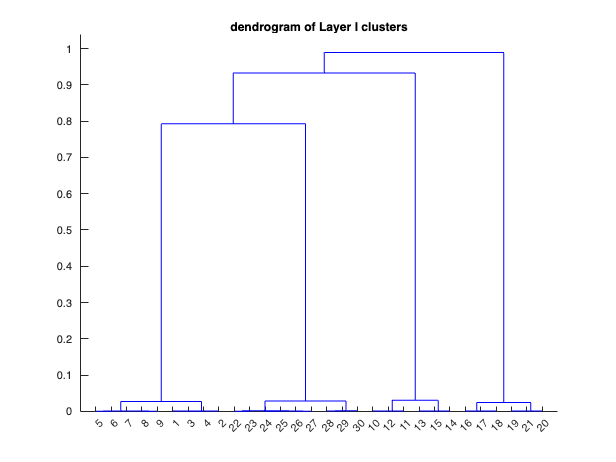

tree1 = linkage(data','average','cosine');
figure;
dendrogram(tree1)
title("dendrogram of Layer I clusters")

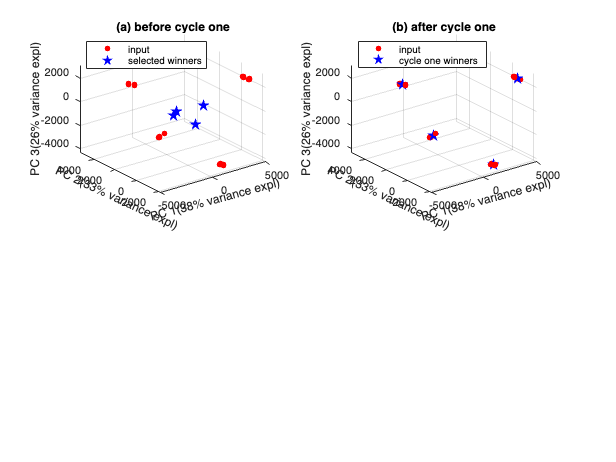


cluster_assign_cycle = zeros(size(data,2),4);

% cycle 1, find the cluster winners
cycle = 1;
ori_cycle1_cells = cells;
cycle1_cells = normc(cells);
cycle1_cells_iter = normc(cells);

for k = 1:20;
    cycle1_winners = [];
    sampled_data = data(:, randperm(size(data, 2)));
    winner_len_mat = [];
    winner_average = zeros(100,1,2500);
    for col = 1:size(sampled_data,2); % loop over all inputs
        lr = 0.009;
        input1 = sampled_data(:,col);% each input
        len_input = norm(input1);
        input1 = normc(input1);
        winner_per_cycle = [];
        product = input1'*cycle1_cells; % the dot products of the input and all cells
        winning_value = max(product); % max dot product value
        winning_idx = find(product == winning_value); % index(indices) of winning cell(s)
        winning_cell = cycle1_cells(:,winning_idx); % the winning cell set, which may contain more than one winning cell
        % loop over each winning cell in the set, in case of tied winners,
        % which may not happen
        updated_winningset = []; % in case of tied winners
        for cell_idx = winning_idx;
            winner = cycle1_cells_iter(:,cell_idx);
            cycle1_winners = [cycle1_winners;cell_idx];
            update_winner_ori = winner+(input1-winner)*lr;
            winner_average(:,:,cell_idx) = update_winner_ori + winner_average(:,:,cell_idx);

            len_update_winner = norm(update_winner_ori);
            update_winner = update_winner_ori/len_update_winner;
            updated_winningset = [updated_winningset;update_winner];
            winner_len_mat = [winner_len_mat;[cell_idx,len_input]];           
            cycle1_cells(:,cell_idx) = update_winner; 
            cycle1_cells_iter(:,cell_idx) = update_winner_ori; 
            %ori_cycle1_cells(:,cell_idx) = update_winner*len_input;
        end
        
    end
end

[~,~,ix] = unique(cycle1_winners,"stable");
winner_stats = [unique(cycle1_winners,"stable"),accumarray(ix,1)];

for i = 1:size(winner_stats,1);
winner_average(:,:,winner_stats(i,1)) = winner_average(:,:,winner_stats(i,1))./winner_stats(i,2);
cycle1_cells(:,winner_stats(i,1)) = winner_average(:,:,winner_stats(i,1)); 
end


% each input wins which?
cycle1_winner=cycle1_winners;
cycle1_winners = unique(cycle1_winners,"stable");
[~,idx] = max(normr(inputs)*cycle1_cells(:,cycle1_winners),[],2);
cluster_assign_cycle(:,cycle) = cycle1_winners(idx);
cycle1_winners = cycle1_winners(unique(idx,"stable")); 


for c = cycle1_winners';
    each_input = winner_len_mat(winner_len_mat(:,1)== c,2);
    ori_cycle1_cells(:,c) = cycle1_cells(:,c)*mean(each_input);
end
cycle1_winner_demask = ori_cycle1_cells(:,cycle1_winners);

% before cycle 1 plots
final_all_data = [inputs;cells(:,cycle1_winners)'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Zb1=final_all_data*coeff(:,1:3);
explained_b = round(explained);

final_all_data = [inputs;mu_mat;ori_cycle1_cells(:,cycle1_winners)'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Za1=final_all_data*coeff(:,1:3);
explained_a = round(explained);

figure;
subplot(2,2,1)
hold on
view(3)
plot3(Zb1(1:length(data),1),Zb1(1:length(data),2),Zb1(1:length(data),3),'r.','MarkerSize',15)
plot3(Zb1(end-3:end,1),Zb1(end-3:end,2),Zb1(end-3:end,3),'bp','MarkerFaceColor','blue','MarkerSize',10)
title("(a) before cycle one")
legend('input','selected winners','Location','NW')
xlabel('PC 1(' + string(explained_b(1))+"% variance expl)")
ylabel('PC 2(' + string(explained_b(2))+"% variance expl)")
zlabel('PC 3(' + string(explained_b(3))+"% variance expl)")
xh = get(gca,'XLabel'); % Handle of the x label
set(xh, 'Units', 'Normalized')
pos = get(xh, 'Position');
set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
yh = get(gca,'YLabel'); % Handle of the y label
set(yh, 'Units', 'Normalized')
pos = get(yh, 'Position');
set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
grid on
hold off


% after cycle 1 plots
subplot(2,2,2)
hold on
view(3)
plot3(Za1(1:length(data),1),Za1(1:length(data),2),Za1(1:length(data),3),'r.','MarkerSize',15)
plot3(Za1(end-3:end,1),Za1(end-3:end,2),Za1(end-3:end,3),'bp','MarkerFaceColor','blue','MarkerSize',10)
title("(b) after cycle one")
legend('input','cycle one winners','Location','NW')
xlabel('PC 1(' + string(explained_a(1))+"% variance expl)")
ylabel('PC 2(' + string(explained_a(2))+"% variance expl)")
zlabel('PC 3(' + string(explained_a(3))+"% variance expl)")
xh = get(gca,'XLabel'); % Handle of the x label
set(xh, 'Units', 'Normalized')
pos = get(xh, 'Position');
set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
yh = get(gca,'YLabel'); % Handle of the y label
set(yh, 'Units', 'Normalized')
pos = get(yh, 'Position');
set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
grid on
hold off

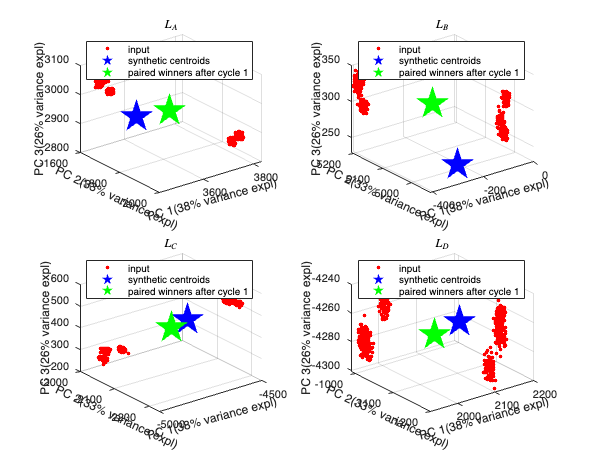




id = ["A","B","C","D"];
figure;

for i = 1:4;
    data_idx = find(cluster_assign_cycle(:,1) == cycle1_winners(i));
    subplot(2,2,i);
    hold on
    view(3) 
    plot3(Za1(data_idx,1),Za1(data_idx,2),Za1(data_idx,3),'r.','MarkerSize',10)
    plot3(Za1(length(data)+i,1),Za1(length(data)+i,2),Za1(length(data)+i,3),'bp','MarkerFaceColor','blue','MarkerSize',30)
    plot3(Za1(length(data)+4+i,1),Za1(length(data)+4+i,2),Za1(length(data)+4+i,3),'gp','MarkerFaceColor','green','MarkerSize',30)
    title("$L_{"+id(i)+"}$", 'Interpreter', 'latex')
    legend('input','synthetic centroids','paired winners after cycle 1','Location','NW')
    xlabel('PC 1(' + string(explained_a(1))+"% variance expl)")
    ylabel('PC 2(' + string(explained_a(2))+"% variance expl)")
    zlabel('PC 3(' + string(explained_a(3))+"% variance expl)")
    xh = get(gca,'XLabel'); % Handle of the x label
    set(xh, 'Units', 'Normalized')
    pos = get(xh, 'Position');
    set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
    yh = get(gca,'YLabel'); % Handle of the y label
    set(yh, 'Units', 'Normalized')
    pos = get(yh, 'Position');
    set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
    grid on
    hold off
end


cycle1_winner_demask = ori_cycle1_cells(:,cycle1_winners);

[~,sort] = min(pdist2(mu_mat,cycle1_winner_demask'),[],2);
cycle1_winner_demask = cycle1_winner_demask(:,sort);
m1 = round(pdist2(mu_mat,cycle1_winner_demask'),1);
m2 = round(pdist2(mu_mat,mu_mat),1);
m3 = round(pdist2(cycle1_winner_demask',cycle1_winner_demask'),1);
T1_cw = array2table(m1)

T1_cw = 4×4 table
     m11       m12       m13       m14  
    ______    ______    ______    ______

     653.9    8291.8    8651.1    7452.7
    8313.4     701.8    8494.3    7946.1
    8709.5    8488.2     718.7    8309.8
    7451.2    8072.5    8368.6     707.1


T1_cc= array2table(m2)

T1_cc = 4×4 table
     m21       m22       m23       m24  
    ______    ______    ______    ______

         0    8287.6    8601.8    7469.2
    8287.6         0    8483.9      8012
    8601.8    8483.9         0    8354.6
    7469.2      8012    8354.6         0


T1_ww = array2table(m3)

T1_ww = 4×4 table
     m31       m32       m33       m34  
    ______    ______    ______    ______

         0    8319.6    8753.4    7438.2
    8319.6         0    8489.2    8011.8
    8753.4    8489.2         0      8323
    7438.2    8011.8      8323         0




[~,p] = ttest2(diag(m1),setdiff(m1,diag(m1))) 

p =    4.2479e-15


[~,p] = ttest2(diag(m1),setdiff(m1,diag(m1)),'Tail','left') 

p =    2.1239e-15




true_label = assign_id3;
assigned_cluster = cluster_assign_cycle(:,1);
PTY1 = purity(assigned_cluster,true_label);
NMI1 = nmi(true_label, assigned_cluster);
[RI1, ARI1] = randindex(true_label, assigned_cluster);
[s1] = ClusterEvalSilhouette(data', assigned_cluster, 'cosine');
ch1 = ClusterEvalCalinskiHarabasz(data', assigned_cluster);
[db1] = ClusterEvalDaviesBouldin(data', assigned_cluster);

% post-cycle 1 subdivide

cluster_label = [assigned_cluster,assign_id3];
unique_cluster = unique(assigned_cluster);
for i = 1:length(unique_cluster)
    assigned = unique_cluster(i);
    labels = cluster_label(find(cluster_label(:,1) == assigned),2);
    num_max_class = numel(find(labels==mode(labels)));

    if length(unique(labels)) ==1 | num_max_class/length(labels) >= 0.85;
        disp('cluster with winner '+string(assigned)+' is not sub-divisive')
    else
        disp('cluster with winner '+string(assigned)+' is sub-divisive')
    end
end

cluster with winner 144 is sub-divisive
cluster with winner 354 is sub-divisive
cluster with winner 1238 is sub-divisive
cluster with winner 1265 is sub-divisive


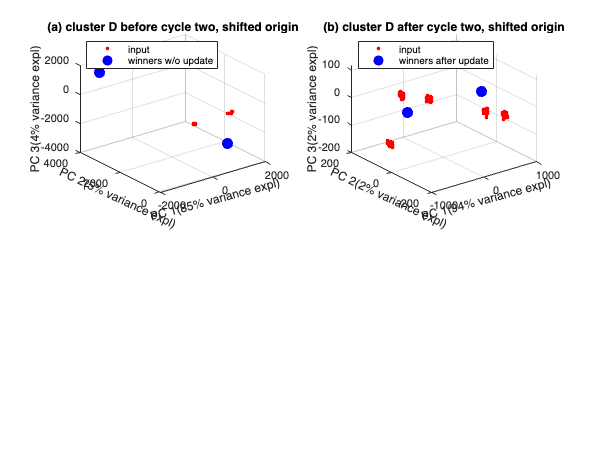

%cycle 2, find the sub-cluster winners
% determine the clutser

cycle = 2;
ori_cycle2_cells = ori_cycle1_cells;
cycle2_cells = cycle1_cells;
cycle2_cells_iter = cycle1_cells;
ori_cycle2_cells(:,cycle1_winners) = 0;
cycle2_cells(:,cycle1_winners) = 0;
cycle2_cells_iter(:,cycle1_winners) = 0;

cycle2_winner_mat = [];
this_winner_mat = [];

for c = 1:size(cycle1_winners,1);
    lr = 0.02;
    this_idx = c;
    this_winner_idx = cycle1_winners(this_idx);
    rawinput_idx = find(cluster_assign_cycle(:,cycle-1) == this_winner_idx);
    sampled_data_fix = data(:,rawinput_idx);  %select each cluster data
    this_winner = ori_cycle1_cells(:,this_winner_idx); % the cell that "this" cluster wins in cycle 1
    sampled_data_fix = sampled_data_fix-this_winner;
    this_winner_mat = [this_winner_mat;this_winner';this_winner'];
    for k = 1:20; % each cluster learns 100 rounds
        winner_len_mat = [];
        cycle2_winners = [];
        sampled_data = sampled_data_fix(:, randperm(size(sampled_data_fix, 2)));
        winner_average = zeros(100,1,2500);
        %sampled_data(1)
        for col = 1:size(sampled_data,2); % loop over all inputs
            input1 = sampled_data(:,col);
            len_input = norm(input1);
            input1 = normc(input1);
            product = input1'*cycle2_cells; % the dot products of the input and all cells
            winning_value = max(product); % max dot product value
            winning_idx = find(product == winning_value);
            for cell_idx = winning_idx;
                winning_cell = cycle2_cells_iter(:,cell_idx);
                cycle2_winners = [cycle2_winners;cell_idx];
                winner_len_mat = [winner_len_mat;[cell_idx,len_input]];
                update_winner = winning_cell+(input1-winning_cell)*lr;
                winner_average(:,:,winning_idx) = update_winner + winner_average(:,:,winning_idx);
                cycle2_cells_iter(:,winning_idx) = update_winner; 
                
                update_winner = normc(update_winner);
                cycle2_cells(:,cell_idx) = update_winner;
                %cycle2_cells_copy(:,cell_idx) = update_winner;
                
            end
        end   
    end

    [~,~,ix] = unique(cycle2_winners,"stable");
    winner_stats = [unique(cycle2_winners,"stable"),accumarray(ix,1)];
    for i = 1:size(winner_stats,1);
        winner_average(:,:,winner_stats(i,1)) = winner_average(:,:,winner_stats(i,1))./winner_stats(i,2);
        cycle2_cells_iter(:,winner_stats(i,1)) = winner_average(:,:,winner_stats(i,1));
    end
    cycle2_winners = unique(cycle2_winners);

    [~,idx] = max(normc(sampled_data_fix)'*cycle2_cells(:,cycle2_winners),[],2);
    cluster_assign_cycle(rawinput_idx,cycle) = cycle2_winners(idx);
    
    cycle2_winners = cycle2_winners(unique(idx,"stable"));

%     [~,idx]= max((center1(2*c-1:2*c,:)-this_winner')*cycle2_cells_copy(:,cycle2_winners),[],2);
%     cycle2_winners = cycle2_winners(idx); % now it's the right #
    cycle2_winner_mat = [cycle2_winner_mat;cycle2_winners];
    
    for c1 = cycle2_winners';
        each_input = winner_len_mat(winner_len_mat(:,1)== c1,2);
        ori_cycle2_cells(:,c1) = cycle2_cells_iter(:,c1)*mean(each_input);
    end
    cycle2_cells(:,cycle2_winners) = 0;
    cycle2_cells_iter(:,cycle2_winners) = 0;
end


cycle2_winnerA_idx = cycle2_winners(1);
cycle2_winnerB_idx = cycle2_winners(2);
cycle2_winnerA_b = ori_cycle1_cells(:,cycle2_winnerA_idx);
cycle2_winnerB_b = ori_cycle1_cells(:,cycle2_winnerB_idx);
cycle2_winnerA = ori_cycle2_cells(:,cycle2_winnerA_idx);
cycle2_winnerB = ori_cycle2_cells(:,cycle2_winnerB_idx);
cycle2_winner_demask = ori_cycle2_cells(:,cycle2_winner_mat)+this_winner_mat';


final_all_data = [sampled_data';cycle2_winnerA_b';cycle2_winnerB_b'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Zb2=final_all_data*coeff(:,1:3);
explained_b = round(explained);

final_all_data = [sampled_data';cycle2_winnerA';cycle2_winnerB'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Za2=final_all_data*coeff(:,1:3);
explained_a = round(explained);

figure;
subplot(2,2,1)
hold on
view(3)
plot3(Zb2(1:600,1),Zb2(1:600,2),Zb2(1:600,3),'r.','MarkerSize',10)
plot3(Zb2(end-1:end,1),Zb2(end-1:end,2),Zb2(end-1:end,3),'b.','MarkerSize',30)
title("(a) cluster D before cycle two, shifted origin")
legend('input','winners w/o update','Location','NW')
xlabel('PC 1(' + string(explained_b(1))+"% variance expl)")
ylabel('PC 2(' + string(explained_b(2))+"% variance expl)")
zlabel('PC 3(' + string(explained_b(3))+"% variance expl)")
xh = get(gca,'XLabel'); % Handle of the x label
set(xh, 'Units', 'Normalized')
pos = get(xh, 'Position');
set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
yh = get(gca,'YLabel'); % Handle of the y label
set(yh, 'Units', 'Normalized')
pos = get(yh, 'Position');
set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
grid on
hold off


subplot(2,2,2)
hold on
view(3)
plot3(Za2(1:600,1),Za2(1:600,2),Za2(1:600,3),'r.','MarkerSize',10)
plot3(Za2(end-1:end,1),Za2(end-1:end,2),Za2(end-1:end,3),'b.','MarkerSize',30)
title("(b) cluster D after cycle two, shifted origin")
legend('input','winners after update','Location','NW')
xlabel('PC 1(' + string(explained_a(1))+"% variance expl)")
ylabel('PC 2(' + string(explained_a(2))+"% variance expl)")
zlabel('PC 3(' + string(explained_a(3))+"% variance expl)")
xh = get(gca,'XLabel'); % Handle of the x label
set(xh, 'Units', 'Normalized')
pos = get(xh, 'Position');
set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
yh = get(gca,'YLabel'); % Handle of the y label
set(yh, 'Units', 'Normalized')
pos = get(yh, 'Position');
set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
grid on
hold off

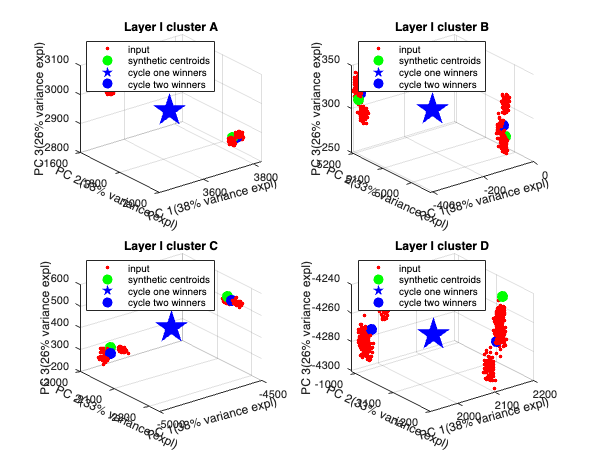


final_all_data = [inputs;center1;cycle1_winner_demask';cycle2_winner_demask'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Z14=final_all_data*coeff(:,1:3);
explained = round(explained);

figure;
for j = 1:4;
    data_idx = find(cluster_assign_cycle(:,1) == cycle1_winners(j));
    subplot(2,2,j);
    hold on
    view(3)
    plot3(Z14(data_idx,1),Z14(data_idx,2),Z14(data_idx,3),'r.','MarkerSize',10)
    plot3(Z14(2399+2*j:2400+2*j,1),Z14(2399+2*j:2400+2*j,2),Z14(2399+2*j:2400+2*j,3),'g.','MarkerSize',30)
    plot3(Z14(2408+j,1),Z14(2408+j,2),Z14(2408+j,3),'bp','MarkerFaceColor','blue','MarkerSize',30)
    plot3(Z14(2411+2*j:2412+2*j,1),Z14(2411+2*j:2412+2*j,2),Z14(2411+2*j:2412+2*j,3),'b.','MarkerSize',30)
    title("Layer I cluster "+id(j))
    legend('input','synthetic centroids','cycle one winners','cycle two winners','Location','NW')
    xlabel('PC 1(' + string(explained(1))+"% variance expl)")
    ylabel('PC 2(' + string(explained(2))+"% variance expl)")
    zlabel('PC 3(' + string(explained(3))+"% variance expl)")
    xh = get(gca,'XLabel'); % Handle of the x label
    set(xh, 'Units', 'Normalized')
    pos = get(xh, 'Position');
    set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
    yh = get(gca,'YLabel'); % Handle of the y label
    set(yh, 'Units', 'Normalized')
    pos = get(yh, 'Position');
    set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
    grid on
    hold off
end


[~,sort] = min(pdist2(center1,cycle2_winner_demask'),[],2);
cycle2_winner_demask = cycle2_winner_demask(:,sort);
m1 = round(pdist2(center1,cycle2_winner_demask'),1);
T2_cw = array2table(m1)

T2_cw = 8×8 table
     m11       m12       m13       m14       m15       m16       m17       m18  
    ______    ______    ______    ______    ______    ______    ______    ______

     107.7    1389.8    8345.9    8668.8    8743.5    9119.4    7469.4      7428
    1407.7     119.7    8084.3    8398.7    8467.8    8864.4    7571.2    7515.9
    8353.6    8090.3     125.8    1493.3    8507.3    8552.7    7838.9    8019.5
    8682.7    8407.2    1499.1     118.7    8537.4    8574.5    8132.7    8287.6
    8756.2    8471.6      8496      8546     121.2    1383.5    8281.2    8394.7
    9115.7    8844.4    8533.1    8575.1    1364.1     108.1    8363.7    8484.4
    7456.2    7560.2    7833.1    8123.6    8265.7    8364.1 

[~,p] = ttest2(diag(m1),setdiff(m1,diag(m1))) 

p =    1.7828e-11




m2 = round(pdist2(center1,center1),1);
T2_cc = array2table(m2)

T2_cc = 8×8 table
     m21       m22       m23       m24       m25       m26       m27       m28  
    ______    ______    ______    ______    ______    ______    ______    ______

         0    1398.9    8344.3    8672.3    8744.5    9102.6      7453    7396.5
    1398.9         0    8083.5    8400.9    8466.7    8842.8    7554.4    7483.6
    8344.3    8083.5         0    1489.6    8500.8    8535.6    7824.5    8005.2
    8672.3    8400.9    1489.6         0    8531.9    8559.4    8120.3    8273.6
    8744.5    8466.7    8500.8    8531.9         0    1370.9      8275      8395
    9102.6    8842.8    8535.6    8559.4    1370.9         0    8358.9    8488.6
      7453    7554.4    7824.5    8120.3      8275    8358.9 

[~,p] = ttest2(diag(m1),setdiff(m2,diag(m2))) 

p =    1.9601e-09



m3 = round(pdist2(cycle2_winner_demask',cycle2_winner_demask'),1);
T2_ww = array2table(m3)

T2_ww = 8×8 table
     m31       m32       m33       m34       m35       m36       m37       m38  
    ______    ______    ______    ______    ______    ______    ______    ______

         0    1398.8    8355.2    8679.3    8755.5    9132.5    7472.7    7428.7
    1398.8         0      8091    8405.1    8472.7      8866    7576.6    7520.8
    8355.2      8091         0    1504.7    8502.4    8550.1    7847.4    8033.2
    8679.3    8405.1    1504.7         0    8551.7    8590.4    8135.8    8290.9
    8755.5    8472.7    8502.4    8551.7         0      1376    8271.8    8384.9
    9132.5      8866    8550.1    8590.4      1376         0    8368.7    8490.1
    7472.7    7576.6    7847.4    8135.8    8271.8    8368.7 

[~,p] = ttest2(diag(m1),setdiff(m3,diag(m3))) 

p =    1.9039e-09


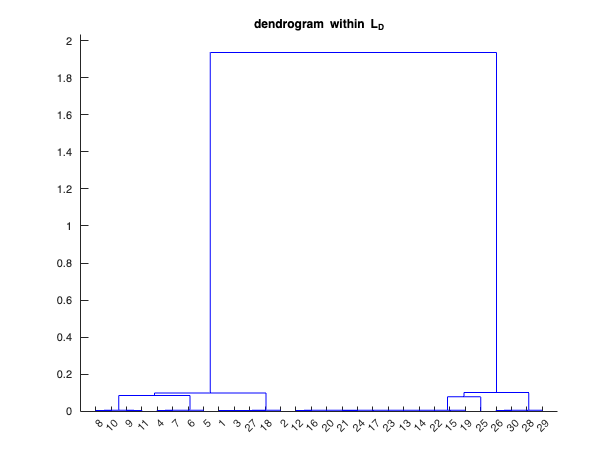



tree2 = linkage(sampled_data_fix','average','cosine');
figure;
dendrogram(tree2)
title("dendrogram within L_{D}")


true_label = assign_id3;
assigned_cluster = cluster_assign_cycle(:,2);
PTY2 = purity(assigned_cluster,true_label);
NMI2 = nmi(true_label, assigned_cluster);
[RI2, ARI2] = randindex(true_label, assigned_cluster);
[s2] = ClusterEvalSilhouette (data', assigned_cluster, 'cosine');
ch2 = ClusterEvalCalinskiHarabasz(data', assigned_cluster);
[db2] = ClusterEvalDaviesBouldin (data', assigned_cluster);

% post-cycle 2 subdivide

cluster_label = [assigned_cluster,assign_id3];
unique_cluster = unique(assigned_cluster);
for i = 1:length(unique_cluster)
    assigned = unique_cluster(i);
    labels = cluster_label(find(cluster_label(:,1) == assigned),2);
    num_max_class = numel(find(labels==mode(labels)));

    if length(unique(labels)) ==1 | num_max_class/length(labels) >= 0.85;
        disp('cluster with winner '+string(assigned)+' is not sub-divisive')
    else
        disp('cluster with winner '+string(assigned)+' is sub-divisive')
    end
end

cluster with winner 152 is sub-divisive
cluster with winner 426 is sub-divisive
cluster with winner 683 is sub-divisive
cluster with winner 1537 is sub-divisive
cluster with winner 1608 is sub-divisive
cluster with winner 2117 is sub-divisive
cluster with winner 2137 is sub-divisive
cluster with winner 2232 is sub-divisive


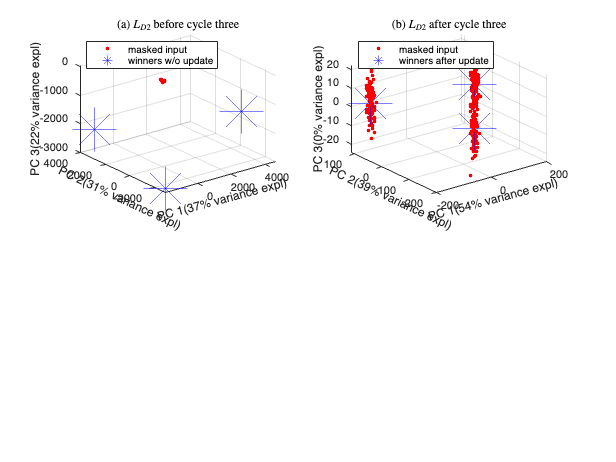

%cycle 3 sub-sub-cluster
cycle = 3;
ori_cycle3_cells = ori_cycle2_cells;
cycle3_cells = cycle2_cells;
cycle3_cells_iter = cycle2_cells;

ori_cycle3_cells(:,cycle2_winner_mat) = 0;
cycle3_cells(:,cycle2_winner_mat) = 0;
cycle3_cells_iter(:,cycle2_winner_mat) = 0;


cycle3_winner_mat = [];
this_winner1_mat = [];
this_winner2_mat = [];

for c = 1:size(cycle2_winner_mat,1);
    this_winner_idx = cycle2_winner_mat(c);
    rawinput_idx = find(cluster_assign_cycle(:,cycle-1) == this_winner_idx);
    sampled_data_fix = data(:,rawinput_idx);

    this_idx_1 = unique(cluster_assign_cycle(rawinput_idx,1));
    this_winner_1 = ori_cycle1_cells(:,this_idx_1);
    this_winner_2 = ori_cycle2_cells(:,cycle2_winner_mat(c));
    this_winner1_mat = [this_winner1_mat;this_winner_1';this_winner_1';this_winner_1'];
    this_winner2_mat = [this_winner2_mat;this_winner_2';this_winner_2';this_winner_2'];
    sampled_data_fix = sampled_data_fix-this_winner_1-this_winner_2;

    for k = 1:20;
        lr = 0.009;
        sampled_data = sampled_data_fix(:, randperm(size(sampled_data_fix, 2)));
        winner_average = zeros(100,1,2500);
        cycle3_winners = [];
        winner_len_mat = [];
        for col = 1:size(sampled_data,2);
            input1 = sampled_data(:,col);
            len_input = norm(input1);
            input1 = normc(input1);
            product = input1'*cycle3_cells;
            winning_value = max(product);
            winning_idx = find(product == winning_value);

            for cell_idx = winning_idx;
                winning_cell = cycle3_cells_iter(:,cell_idx);
                cycle3_winners = [cycle3_winners;cell_idx];
                winner_len_mat = [winner_len_mat;[cell_idx,len_input]];
                update_winner = winning_cell+(input1-winning_cell)*lr;
                winner_average(:,:,cell_idx) = update_winner + winner_average(:,:,cell_idx);
                %cycle3_cells_copy(:,cell_idx) = update_winner;
                cycle3_cells_iter(:,cell_idx) = update_winner;
                update_winner = normc(update_winner);
                cycle3_cells(:,cell_idx) = update_winner;

            end
        end
    end



    [~,~,ix] = unique(cycle3_winners,"stable");
    winner_stats = [unique(cycle3_winners,"stable"),accumarray(ix,1)];
    %
    for k = 1:size(winner_stats,1);
        winner_average(:,:,winner_stats(k,1)) = winner_average(:,:,winner_stats(k,1))./winner_stats(k,2);
        cycle3_cells_iter(:,winner_stats(k,1)) = winner_average(:,:,winner_stats(k,1));
    end

    [~,idx] = max(normc(sampled_data_fix)'*cycle3_cells(:,cycle3_winners),[],2);
    cluster_assign_cycle(rawinput_idx,cycle) = cycle3_winners(idx);
    cycle3_winners = cycle3_winners(unique(idx,"stable"));


    %          [~,idx]= max((center(3*c-2:3*c,:)-this_winner_1'-this_winner_2')*cycle3_cells(:,cycle3_winners),[],2);
    %          cycle3_winners = cycle3_winners(idx); % now it's the right #
    cycle3_winner_mat = [cycle3_winner_mat;cycle3_winners];

    for c1 = cycle3_winners';
        each_input = winner_len_mat(winner_len_mat(:,1)== c1,2);
        ori_cycle3_cells(:,c1) = cycle3_cells_iter(:,c1)*mean(each_input);
    end
    cycle3_cells(:,cycle3_winners) = 0;
    cycle3_cells_iter(:,cycle3_winners) = 0;
end

cycle3_winnerA_idx = cycle3_winner_mat(22);
cycle3_winnerB_idx = cycle3_winner_mat(23);
cycle3_winnerC_idx = cycle3_winner_mat(24);
cycle3_winnerA = ori_cycle3_cells(:,cycle3_winnerA_idx);
cycle3_winnerB = ori_cycle3_cells(:,cycle3_winnerB_idx);
cycle3_winnerC = ori_cycle3_cells(:,cycle3_winnerC_idx);

cycle3_winnerA_b = ori_cycle2_cells(:,cycle3_winnerA_idx);
cycle3_winnerB_b = ori_cycle2_cells(:,cycle3_winnerB_idx);
cycle3_winnerC_b = ori_cycle2_cells(:,cycle3_winnerC_idx);

final_all_data = [sampled_data';cycle3_winnerA_b';cycle3_winnerB_b';cycle3_winnerC_b'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Zb3=final_all_data*coeff(:,1:3);
explained_b = round(explained);

final_all_data = [sampled_data';cycle3_winnerA';cycle3_winnerB';cycle3_winnerC'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Za3=final_all_data*coeff(:,1:3);
explained_a = round(explained);


figure;
subplot(2,2,1);hold on
view(3)
plot3(Zb3(1:300,1),Zb3(1:300,2),Zb3(1:300,3),'r.','MarkerSize',10)
plot3(Zb3(end-2:end,1),Zb3(end-2:end,2),Zb3(end-2:end,3),'b*','MarkerSize',40)
title("(a) $L_{D2}$ before cycle three", 'Interpreter', 'latex')
legend('masked input','winners w/o update','Location','NW')
xlabel('PC 1(' + string(explained_b(1))+"% variance expl)")
ylabel('PC 2(' + string(explained_b(2))+"% variance expl)")
zlabel('PC 3(' + string(explained_b(3))+"% variance expl)")
xh = get(gca,'XLabel'); % Handle of the x label
set(xh, 'Units', 'Normalized')
pos = get(xh, 'Position');
set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
yh = get(gca,'YLabel'); % Handle of the y label
set(yh, 'Units', 'Normalized')
pos = get(yh, 'Position');
set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
grid on
hold off

subplot(2,2,2)
hold on
view(3)
plot3(Za3(1:300,1),Za3(1:300,2),Za3(1:300,3),'r.','MarkerSize',10)
plot3(Za3(end-2:end,1),Za3(end-2:end,2),Za3(end-2:end,3),'b*','MarkerSize',40)
title("(b) $L_{D2}$ after cycle three", 'Interpreter', 'latex')
legend('masked input','winners after update','Location','NW')
xlabel('PC 1(' + string(explained_a(1))+"% variance expl)")
ylabel('PC 2(' + string(explained_a(2))+"% variance expl)")
zlabel('PC 3(' + string(explained_a(3))+"% variance expl)")
xh = get(gca,'XLabel'); % Handle of the x label
set(xh, 'Units', 'Normalized')
pos = get(xh, 'Position');
set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
yh = get(gca,'YLabel'); % Handle of the y label
set(yh, 'Units', 'Normalized')
pos = get(yh, 'Position');
set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
grid on
hold off

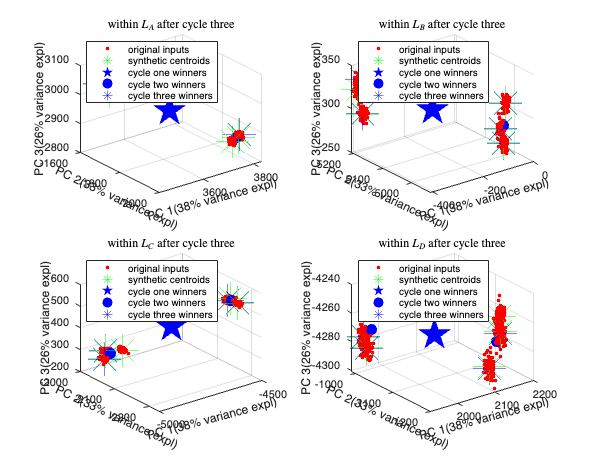



cycle3_winner_demask = ori_cycle3_cells(:,cycle3_winner_mat)+this_winner1_mat'+this_winner2_mat';
final_all_data = [inputs;center;cycle1_winner_demask';cycle2_winner_demask';cycle3_winner_demask'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Z14=final_all_data*coeff(:,1:3);
explained = round(explained);



id = ["A","B","C","D"];
figure;
for j = 1:4;
    data_idx = find(cluster_assign_cycle(:,1) == cycle1_winners(j));
    subplot(2,2,j);
    hold on
    view(3)
    plot3(Z14(data_idx,1),Z14(data_idx,2),Z14(data_idx,3),'r.','MarkerSize',10)
    plot3(Z14(2400+6*j-5:2400+6*j,1),Z14(2400+6*j-5:2400+6*j,2),Z14(2400+6*j-5:2400+6*j,3),'g*','MarkerSize',30)
    plot3(Z14(2424+j,1),Z14(2424+j,2),Z14(2424+j,3),'bp','MarkerFaceColor','blue','MarkerSize',30)
    plot3(Z14(2428+2*j-1:2428+2*j,1),Z14(2428+2*j-1:2428+2*j,2),Z14(2428+2*j-1:2428+2*j,3),'b.','MarkerSize',30)
    plot3(Z14(2436+6*j-5:2436+6*j,1),Z14(2436+6*j-5:2436+6*j,2),Z14(2436+6*j-5:2436+6*j,3),'b*','MarkerSize',30)
    title("within $L_{"+id(j)+"}$ after cycle three", 'Interpreter', 'latex')
    legend('original inputs','synthetic centroids','cycle one winners','cycle two winners','cycle three winners','Location','NW')
    xlabel('PC 1(' + string(explained(1))+"% variance expl)")
    ylabel('PC 2(' + string(explained(2))+"% variance expl)")
    zlabel('PC 3(' + string(explained(3))+"% variance expl)")
    xh = get(gca,'XLabel'); % Handle of the x label
    set(xh, 'Units', 'Normalized')
    pos = get(xh, 'Position');
    set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
    yh = get(gca,'YLabel'); % Handle of the y label
    set(yh, 'Units', 'Normalized')
    pos = get(yh, 'Position');
    set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
    grid on
    hold off
end

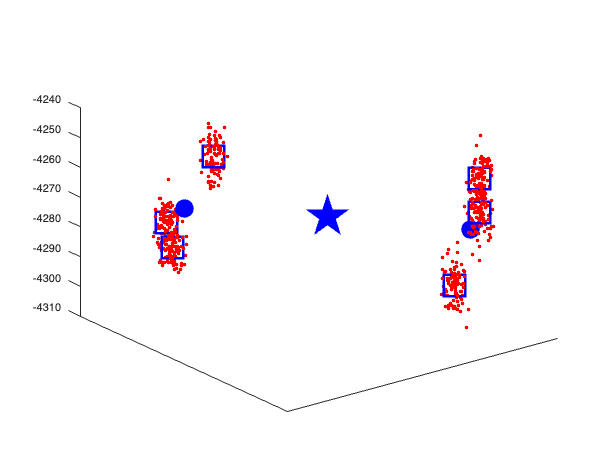


j = 4;
figure;
hold on
view(3)
plot3(Z14(data_idx,1),Z14(data_idx,2),Z14(data_idx,3),'r.','MarkerSize',10)
plot3(Z14(2424+j,1),Z14(2424+j,2),Z14(2424+j,3),'bp','MarkerFaceColor','blue','MarkerSize',40)
plot3(Z14(2428+2*j-1:2428+2*j,1),Z14(2428+2*j-1:2428+2*j,2),Z14(2428+2*j-1:2428+2*j,3),'b.','MarkerFaceColor','blue','MarkerSize',50)
plot3(Z14(2436+6*j-5:2436+6*j,1), Z14(2436+6*j-5:2436+6*j,2), Z14(2436+6*j-5:2436+6*j,3), 'bs', 'MarkerSize', 25, 'LineWidth', 3)
 %,'MarkerFaceColor','blue',
%legend('inputs','cycle one','cycle two','cycle three','Location','NW')
set(gca,'XTick',[], 'YTick', [])
hold off

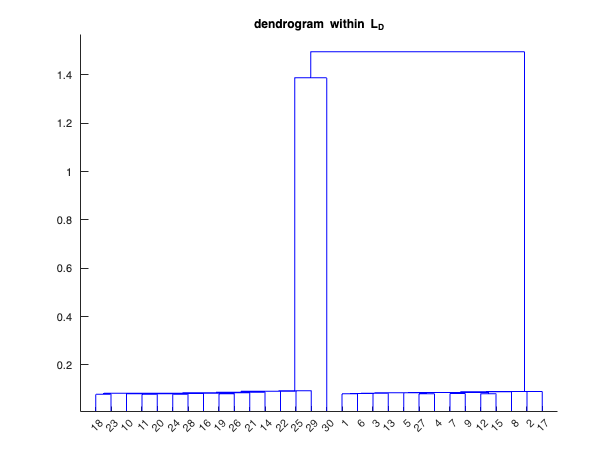



tree2 = linkage(sampled_data_fix','average','cosine');
figure;
dendrogram(tree2)
title("dendrogram within L_{D}")

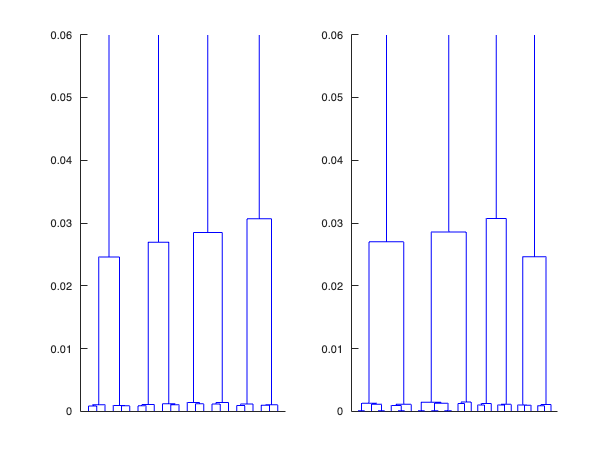


tree3 = linkage(cycle3_winner_demask','average','cosine');
figure;
subplot(1,2,1)
dendrogram(tree3)
%title("LI-HC")
set(gca,'XTick',[])
ylim([0 0.06])
subplot(1,2,2)
dendrogram(tree1)
%title("Original")
set(gca,'XTick',[])
ylim([0 0.06])


[~,sort] = min(pdist2(center,cycle3_winner_demask'),[],2);
cycle3_winner_demask = cycle3_winner_demask(:,sort);
m1 = round(pdist2(center,cycle3_winner_demask'),1);
T3_cw = array2table(m1);
[~,p] = ttest2(diag(m1),setdiff(m1,diag(m1))) 

p =      2.05e-24


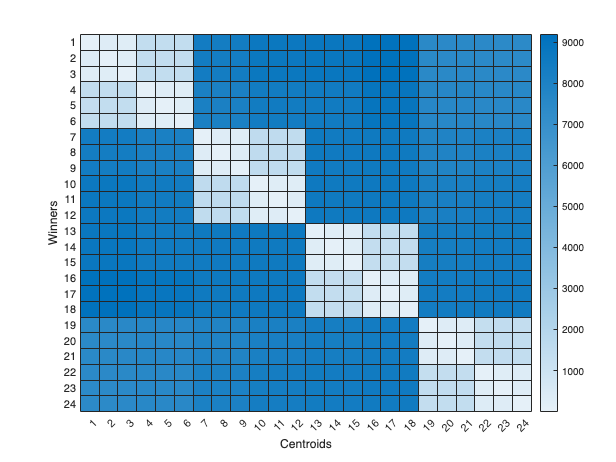

figure;
heatmap(T3_cw{:,:});
xlabel('Centroids');
ylabel('Winners');



m2 = round(pdist2(center,center),1);
T3_cc = array2table(m2)
[~,p] = ttest2(diag(m1),setdiff(m2,diag(m2))) 
figure;
heatmap(T3_cc{:,:});
xlabel('Centroids');
ylabel('Centroids');

m3 = round(pdist2(cycle3_winner_demask',cycle3_winner_demask'),1);
T3_ww = array2table(m3)
[~,p] = ttest2(diag(m1),setdiff(m3,diag(m3))) 
figure;
heatmap(T3_ww{:,:});
xlabel('Winners');
ylabel('Winners');


%metrics
tree3 = linkage(sampled_data_fix','average','cosine');
figure;
dendrogram(tree3)
title("dendrogram within L_{D2}")

true_label = assign_id3;
assigned_cluster = cluster_assign_cycle(:,3);
PTY3 = purity(assigned_cluster,true_label);
NMI3 = nmi(true_label, assigned_cluster);
[RI3, ARI3] = randindex(true_label, assigned_cluster);
[s3] = ClusterEvalSilhouette (data', assigned_cluster, 'cosine');
ch3 = ClusterEvalCalinskiHarabasz(data', assigned_cluster);
[db3] = ClusterEvalDaviesBouldin (data', assigned_cluster);

cluster_label = [assigned_cluster,assign_id3];
unique_cluster = unique(assigned_cluster);
for i = 1:length(unique_cluster)
    assigned = unique_cluster(i);
    labels = cluster_label(find(cluster_label(:,1) == assigned),2);
    num_max_class = numel(find(labels==mode(labels)));

    if length(unique(labels)) ==1 | num_max_class/length(labels) >= 0.85;
        disp('cluster with winner '+string(assigned)+' is not sub-divisive')
    else
        disp('cluster with winner '+string(assigned)+' is sub-divisive')
    end
end

% try cycle 4, expect many  winners under each cycle 3 winner


cycle = 4;
ori_cycle4_cells = ori_cycle3_cells;
cycle4_cells = cycle3_cells;
cycle4_cells_iter = cycle3_cells;

ori_cycle4_cells(:,cycle3_winner_mat) = 0;
cycle4_cells(:,cycle3_winner_mat) = 0;
cycle4_cells_iter(:,cycle3_winner_mat) = 0;

cycle4_assignment = {};

cycle4_winners_mat = [];


for c = 1:size(cycle3_winner_mat,1);
    this_idx_3 = cycle3_winner_mat(c);
    rawinput_idx = find(cluster_assign_cycle(:,cycle-1) == this_idx_3);
    this_idx_1 = unique(cluster_assign_cycle(rawinput_idx,1));
    this_idx_2 = unique(cluster_assign_cycle(rawinput_idx,2));

    this_winner_1 = ori_cycle1_cells(:,this_idx_1);
    this_winner_2 = ori_cycle2_cells(:,this_idx_2);
    this_winner_3 =ori_cycle3_cells(:,this_idx_3);

    sampled_data_fix = data(:,rawinput_idx);
    sampled_data_fix = sampled_data_fix-this_winner_1-this_winner_2-this_winner_3;
    order = [1:size(sampled_data_fix,1)];
    sampled_data_fix = [sampled_data_fix;order];

    for k = 1:20;
        lr = 0.009;
        reor_sampled_data_fix = sampled_data_fix(:, randperm(size(sampled_data_fix, 2)));
        sampled_data = reor_sampled_data_fix(1:end-1,:);
        reorder = reor_sampled_data_fix(end,:); % remember the order of the shuffled data

        winner_average = zeros(100,1,2500);
        cycle4_winners = [];
        winner_len_mat = [];
        for col = 1:size(sampled_data,2);
            input1 = sampled_data(:,col);
            len_input = norm(input1);
            input1 = normc(input1);
            product = input1'*cycle4_cells;
            winning_value = max(product);
            winning_idx = find(product == winning_value);

            for cell_idx = winning_idx;
                winning_cell = cycle4_cells_iter(:,cell_idx);
                cycle4_winners = [cycle4_winners;cell_idx];
                winner_len_mat = [winner_len_mat;[cell_idx,len_input]];
                update_winner = winning_cell+(input1-winning_cell)*lr;
                winner_average(:,:,cell_idx) = update_winner + winner_average(:,:,cell_idx);
                cycle4_cells_iter(:,cell_idx) = update_winner;
                update_winner = normc(update_winner);
                cycle4_cells(:,cell_idx) = update_winner;
            end
        end
    end

%     [~,idx] = max(normc(sampled_data_fix)'*cycle4_cells(:,cycle4_winners),[],2);
     reorder_cycle4_winners = zeros(length(cycle4_winners),1);
     reorder_cycle4_winners(reorder) = cycle4_winners;
     cluster_assign_cycle(rawinput_idx,cycle) = reorder_cycle4_winners;
    

    cycle4_winners_mat = [cycle4_winners_mat;reorder_cycle4_winners];
    cycle4_cells(:,cycle4_winners) = 0;
    cycle4_cells_iter(:,cycle4_winners) = 0;
    cycle4_assignment{c} = cycle4_winners;

end


tree4 = linkage(sampled_data','average','cosine');
figure;
dendrogram(tree4)
title("dendrogram within L_{D2\gamma}")

figure;
subplot(2,2,1)
dendrogram(tree1)
title("dendrogram of all data", 'Interpreter', 'latex')
subplot(2,2,2)
dendrogram(tree2)
title('dendrogram within $L_{D}$', 'Interpreter', 'latex')
subplot(2,2,3)
dendrogram(tree3)
title("dendrogram within $L_{D2}$", 'Interpreter', 'latex')
subplot(2,2,4)
dendrogram(tree4)
title("dendrogram within $L_{D2\gamma}$", 'Interpreter', 'latex')


true_label = assign_id3;
assigned_cluster = cluster_assign_cycle(:,4);
PTY4 = purity(assigned_cluster,true_label);
NMI4 = nmi(true_label, assigned_cluster);
[RI4, ARI4] = randindex(true_label, assigned_cluster);
[s4] = ClusterEvalSilhouette (inputs, assigned_cluster, 'cosine');
ch4 = ClusterEvalCalinskiHarabasz(inputs, assigned_cluster);
[db4] = ClusterEvalDaviesBouldin (inputs, assigned_cluster);

PTY = [PTY1;PTY2;PTY3;PTY4];
NMI = [NMI1;NMI2;NMI3;NMI4];
RI = [RI1;RI2;RI3;RI4];
s = [s1;s2;s3;s4];
ch = [ch1;ch2;ch3;ch4];
db = [db1;db2;db3;db4];


figure;
subplot(2,3,1)
plot(PTY,'-*')
title("Purity")
xlabel('cycles')
subplot(2,3,2)
plot(NMI,'-*')
title("Normalized Mutual Info")
xlabel('cycles')
subplot(2,3,3)
plot(RI,'-*')
title("Rand Index")
xlabel('cycles')
subplot(2,3,4)
plot(s,'-*')
title("Silhouette Coefficient")
xlabel('cycles')
subplot(2,3,5)
plot(ch,'-*')
title("Calinski-Harabasz Index")
xlabel('cycles')
subplot(2,3,6)
plot(db,'-*')
title("Davies-Bouldin Index")
xlabel('cycles')

PTY = [PTY1; PTY2; PTY3];
NMI = [NMI1; NMI2; NMI3];
RI = [RI1; RI2; RI3];
s = [s1; s2; s3];
ch = [ch1; ch2; ch3];
db = [db1; db2; db3];

% Create the table
T = table(PTY, NMI, RI, s, ch, db);
% Set row names
T.Properties.RowNames = {'cycle 1', 'cycle 2', 'cycle 3'};
% Display the table
disp(T);

cycle4_individual = [];
for c = 1:size(cycle3_winner_mat,1);
    this_idx_3 = cycle3_winner_mat(c);
    rawinput_idx = find(cluster_assign_cycle(:,cycle-1) == this_idx_3);
    X = data(:,rawinput_idx)';
    assigned_cluster = cluster_assign_cycle(rawinput_idx,4);
    [s4] = ClusterEvalSilhouette (X', assigned_cluster, 'cosine');
    ch4 = ClusterEvalCalinskiHarabasz(X', assigned_cluster);
    [db4] = ClusterEvalDaviesBouldin (X', assigned_cluster);
    cycle4_individual = [cycle4_individual,[s4;ch4;db4]];
end


% rescaled dendrogram
X_cell = {};
leaf_cell = [];
winner_order = unique(cluster_assign_cycle(:,3),'stable');
for c = 1:size(winner_order,1);
    this_winner = winner_order(c);
    data_idx = find(cluster_assign_cycle(:,3) == this_winner);
    X = data(:,data_idx)';
    Z = linkage(X);
    max_leaf = max(max(Z(:,1:2))); 
    X_cell{c} = X;
    leaf_cell = [leaf_cell;max_leaf];
end

labels = [ones(size(X_cell{1},1),1)];
X_total = X_cell{1};
for i = 2:size(winner_order,1);
    X_total = [X_total;X_cell{i} + sum(leaf_cell(1:i-1))];
    num = size(X_cell{i},1);
    labels = [labels;i*ones(num,1)];
end
str_labels = cellstr(num2str(labels, 'label %d'));
X_total1 = X_total;
X_total1 = [X_total1;X_total1(end-10:end,:)+1000;X_total1(end-10:end,:)+10000];
Z = linkage(X_total);
Z1 = linkage(X_total1);
Z1(end,3) = 12000;
figure;
h = dendrogram(Z1,200);
set(gca, 'XTickLabel', []);

layer1_c_link = linkage(cycle1_winner_demask');l1 = size(layer1_c_link,1);
layer2_c_link = linkage(cycle2_winner_demask');l2 = size(layer2_c_link,1);
layer3_c_link = linkage(cycle3_winner_demask');l3 = size(layer3_c_link,1);
centers_link = layer3_c_link(:,3);
centers_link(end-l1+1:end) = layer1_c_link(end-l1+1:end,3);
centers_link(end-l2+1:end-l1) = layer2_c_link(end-l2+1:end-l1,3);L = size(centers_link,1);

Z(end-L+1:end,3) = centers_link;
figure;
subplot(2,2,1)
h = dendrogram(Z,200,'Labels',str_labels');
title("(a) Dendrogram by LI-HC")
ylabel('rescaled Euclidean dist')
set(gca, 'XTickLabel', []);
subplot(2,2,2)
h = dendrogram(Z,200,'Labels',str_labels');
title("(b) Dendrogram by DHC")
ylabel('rescaled Euclidean dist')
set(gca, 'XTickLabel', []);